# One-box climate model in MATLAB

#### Introduction

This document provides an outline for your first 1-box (blackbody) climate model. You should add your own comments with units and other explanation wherever appropriate.

% Add description of your model in header comments


#### Parameter definitions

% Define model specific parameters (Solar constant (S), radius (r),
% albedo(a))
S = 1361; % solar constant watts/m^2 at 1 au (Kopp & Lean, 2011) Earlier value was 1365
r = 6.371e6; % mean earth radius, m
a = 0.3; %albedo, unitless

% Define initial temperature (T0)
T0 = 223; %deg K, Snowball Earth, using modeled values at -50 C for an Earth (avg global temperature in a snowball)
E0 = 9.99614501304554e+26; %joules, Snowball Earth, using modeled values at -50 C for an Earth (avg global temperature in a snowball)
A0 = 1.82372623148013e+26; %joules, Snowball Earth, using modeled values at -50 C for an Earth (avg global temperature in a snowball)
AT0 = 37.4; %deg K, Snowball Earth, using modeled values at -50 C for an Earth (avg global temperature in a snowball)

% Define energy stock (reservoir) properties
% Earth size parameters
SA = 4.*pi.*r^2; %Surface area, meters squared
xca = pi.*r^2; %Cross sectional area, meters squared
watercov = 0.7; %Proportion of Earth's surface covered by water, unitless

% (thickness (h), density (rho), specific heat(c))
depth = 3000; %assuming a 3500 meter deep ocean
volume = SA.*depth.*watercov; %volume of the ocean, meters cubed
rho = 1000; %density, kg per meters cubed

% Define constants (Stefan-Boltzmann (sigma) and yr2sec)
sigma = 5.67e-8; %Stefan-Boltzmann constant, W/(M^2*K^4)
yr2sec = 365.24219*24*3600; % assuming solar year

% Heat Capacity
specific = 4184; %Specific heat of water, Joules per Kilogram per Degrees Kelvin
capacity = specific.*volume.*rho; %Joules per degrees Kelvin

**Atmospheric Parameters**

height = 10000*1000; %height of the atmosphere, meters
volAtm = SA.*height; %volume of the atmosphere, meters cubed
specAtm = 750; %specific heat of the atmosphere, 
rhoAtm = 1.2754; %density of atmosphere, kg per meters cubed
capAtm = specAtm.*volAtm.*rhoAtm; %Joules per degrees Kelvin
GHG = 0.5; %emissivity back to earth

#### Define model time vector

% Calculate steady-state temperature (Tss), energy (Ess) and
% residence time (Tr)

Tss = 302.7;
%Tss = ((1-a).*S./(4*sigma))^(1/4); %Steady state temperature
Ess = Tss.*capacity; %Steady state energy
Tr = Ess./(S.*xca)./yr2sec; %Residence time

% Define time domain (t) from 0 to 10 residence times and step by 1/10
% residence time
t = 0:(0.1*Tr):(10*Tr); %time
dt = 0.1*Tr; %time step (one unit of the time domain t)


#### Initialize variables and set initial conditions

% Create empty variables to store model solution (energy (E) and
% temperature (T))
E = zeros(length(t),1);
T = zeros(length(t),1);
A = zeros(length(t),1); %Atmospheric energy solution
AT = zeros(length(t),1); %Temperature of the atmosphere
%Define albedo
a = zeros(length(t),1);
a(1) = 0.6; %albedo value for snowball earth

%reflected = zeros(length(t),1);

% Populate the initial values
E(1) = E0; %initial energy value
T(1) = T0; %initial temperature value
A(1) = A0; %initial atmospheric energy value
AT(1) = AT0; %initial atmospheric temperature value

#### Model Solution

% Solve problem using the Forward Euler method
% start with a loop (n) from t(1) to t(end-1)

Fluxin = S.*xca; %solar flux to Earth, watts

for n = 1:length(t)-1

    reflected = Fluxin.*a; %amount of fluxin reflected in a given time step
    Solarin = Fluxin-reflected;

    % Calculate individual components of the energy balance at current
    % time step (n)
    fluxout = sigma.*SA.*(T(n)^4); %irradiance of the Earth, watts - CORRECT
    fluxearthatm = (sigma.*SA.*(AT(n)^4)); %flux to earth of atmospheric energy - CORRECT
    
    % atmospheric capacity
    dAdt = fluxout-(2.*fluxearthatm); %derivative balance of atmosphere using SA of earth
    
    % Calculate the derivative (balance) at the current time step (n)
    dEdt = (Solarin+fluxearthatm-fluxout); %time units in seconds
    
    % Calculate the energy at next time step (n+1) using the current 
    % derivatives and forward Euler method (express time step in seconds).
    %E(n+1) = E(n)+(dEdt(n)).*dt;
    E(n+1) = E(n)+dEdt(n)*dt*yr2sec;
    T(n+1) = (E(n+1)/(capacity)); %calculates temperature from energy at each time step, converts to years
    A(n+1) = A(n)+dAdt*dt*yr2sec; %calculates atmospheric energy balance at each step
    AT(n+1) = (A(n+1)/(capAtm)); %calculates atmospheric temperature from energy at each time step, converts to years
    if (0.3 < a(n)) && a(n) < 0.9
    a(n+1) = a(1) + -0.0056*(T(n)-T0);
    elseif a(n) >= 0.9
    a(n+1) = 0.9;
    elseif a(n) <= 0.3
    a(n+1) = 0.3;
    end

    % Calculate the temperature at next time step (n+1) from the energy

% end your loop
end

**Visualizing Results**

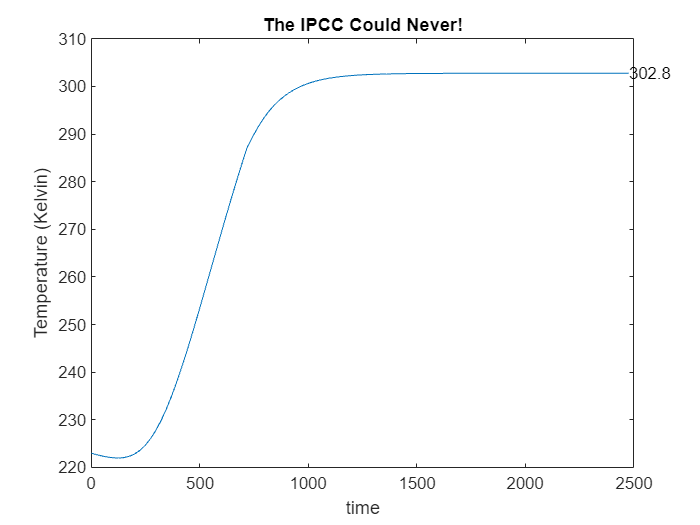

% Plot temperature results, label axes, add title
figure
plot(t, T)
hold on
xlabel('time')
ylabel('Temperature (Kelvin)')
title('The IPCC Could Never!')
% add label with final model temperature (Tm(end)) plotted on graph at last
% time and temperature
text(t(end),T(end),num2str(T(end),'%4.1f'));
hold off

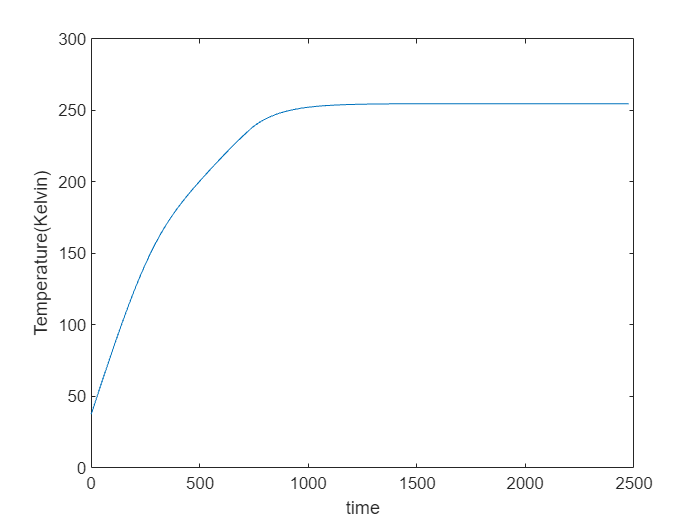

figure
plot(t,AT)
hold on
xlabel('time')
ylabel('Temperature(Kelvin)')